# HW3

## Task 1

(Copy and adjustmet to the HW2 task c))

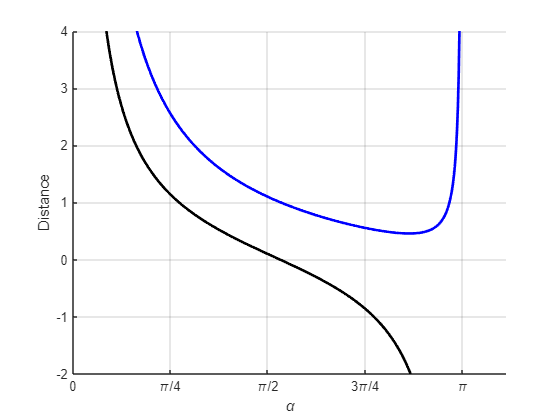

syms alpha
eta_value = [0.1, 1.1];
L = 1; % river width

distance = @(alpha, eta) L * (cos(alpha) ./ sin(alpha)) + (L * eta ./ sin(alpha));% defining function to be used for ploting
alpha_values = linspace(0.01, pi-0.01, 100); % avoid division by 0

% graph
alphas = linspace(0.01, pi, 500);  % Alpha angles in radians

% Plot the distance for different eta values
figure;
hold on;

% Colors for each eta value
colors = {'k', 'b'};  
optimal_alphas = [180, 155];  % Approximate optimal angles for eta= {0.1, 1.1} in degrees (retyped from terminal)
optimal_alphas_rad = deg2rad(optimal_alphas);  % Convert to radians

for i = 1:length(eta_value)
    eta = eta_value(i);
    distances = distance(alphas, eta);
    plot(alphas, distances, colors{i}, 'LineWidth', 2);
end

% Labels and legend
xlabel('\alpha');
ylabel('Distance');
xticks([0, pi/4, pi/2, 3*pi/4, pi]);
xticklabels({'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'});
ylim([-2 4]);

grid on;
hold off;

## Task 2

eta_value = 0.1:0.1:0.9

eta_value =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


optimal_angles = zeros(size(eta_value));

for i = 1:length(eta_value)
    eta = eta_value(i);
    optimal_angles(i) = NEWTONS_METHOD(eta, pi/2, 1e-6, 100);
    fprintf('Optimal angle for eta=%.1f is %.2f°\n', eta, rad2deg(optimal_angles(i)));
end

Optimal angle for eta=0.1 is 95.74°
Optimal angle for eta=0.2 is 101.54°
Optimal angle for eta=0.3 is 107.46°
Optimal angle for eta=0.4 is 113.58°
Optimal angle for eta=0.5 is 120.00°
Optimal angle for eta=0.6 is 126.87°
Optimal angle for eta=0.7 is 134.43°
Optimal angle for eta=0.8 is 143.13°
Optimal angle for eta=0.9 is 154.16°
